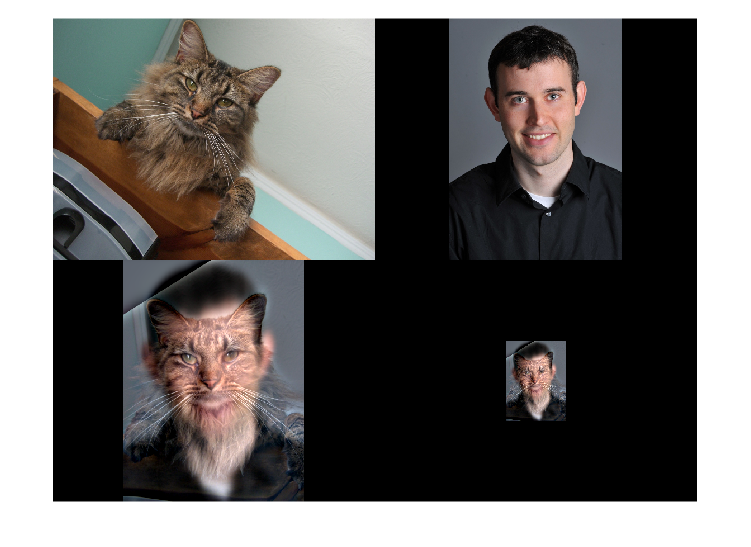

%{

YOUR COMMENTS:

The effect of this effect is to blend the two pictures together to display
a hybrid picture

All of the cutoff values are derived from trial and error. I tried multiple
values to choose the best on that would be good for the given set of
pictures

Spidermans：The first set of picture I chose was the two spider man, in conclusion, I
thik the two spiderman actors do look alike

girls: The second set of pictures I chose is from my artwork. I chose these
two portrait that I drew because I thought it would be cool to merge two
artworks together, but I think because both of the portraits are too bold
and color are vastly different, thus this would be a good example to use as
something that is not suited for this effect.

Me and my bestfriend: I chose a picture of me and my dog to show similar
effect as the first set of pic given by professor

Communism: I chose the two communist leader to combine them as one. 

Zonkey:I combined a zebra and a donkey to create a "zonkey" 

%}

close('all');    % Close all figures so we start with a clean slate

% read images and convert to single format
set1_far = im2double(imread('./derek.jpg')); 		        % "far" picture
set1_near = im2double(imread('./nutmeg.jpg')); 	    		% "near" picture
% (Optional) convert to grayscale
%set1_far = rgb2gray(set1_far)
%set1_near = rgb2gray(set1_near);


% Uncomment the call to get_points_interactively() to set the corresponding
% points in the two images to establish alignment (e.g., by the eyes).
% The function performs translation, rotation and scaling to align those 
% two points in the two images.
%[x1, y1, x2, y2] = get_points_interactively(set1_near, set1_far);
x1 = [605.1403 758.9682]; y1 = [287.3709 360.6136];
x2 = [303.8974 442.5175]; y2 = [348.1681 332.5175];
[set1_near_aligned, set1_far_aligned] = align_images(set1_near, set1_far, x1, y1, x2, y2);


%% Choose the cutoff frequencies for the low-pass and high-pass filters
cutoff_low  = 15.0;   % provide a value for the low-pass filter cutoff frequency (sigma of gaussian).  CHOOSE CAREFULLY!
cutoff_high = 10.0;   % provide a value for the high-pass filter cutoff frequency (sigma of gaussian).  CHOOSE CAREFULLY!

%% Compute the hybrid image (you supply this code)

set1_hybrid = hybridImage(set1_far_aligned, set1_near_aligned, cutoff_low, cutoff_high);

%% Crop resulting image:  Crop the result to get rid of any unsightly borders areas.
%disp('input crop points (two opposite corners)');
%fig=figure; hold off, imagesc(set2_hybrid), axis image;
%figure(fig)
%[x, y] = ginput(2);  x = round(x); y = round(y);
%close(fig);
% Once you these coordinates, uncomment the lines above, and 
% hard code the values below.
x = [90 680]; y = [370 1160];
set1_hybrid = set1_hybrid(min(y):max(y), min(x):max(x), :);

% Let us try to "simulate" what the hybrid image will look like
% when viewed from afar.  Let us pad a black border around it
% so it effectively shrinks in size when displayed in a montage.
[h, w, ~] = size(set1_hybrid);
viewed_from_afar = padarray(set1_hybrid, max(h, w));
figure; montage({set1_near, set1_far, set1_hybrid, viewed_from_afar}, 'Size', [2,2]);



%%
% -------------------------------------------------------------------------
% IMPORTANT NOTE (please read carefully)
% -------------------------------------------------------------------------
% Repeat your method for 5 more sets of images.  But remember that for
% these you must interactively specify the mask and alignment ONE TIME.
%
% Work in the Matlab computer app or the full Matlab Online version
% (https://matlab.mathworks.com) first to get the coordinates for alignment
% and cropping.  Then hard-code these in your program before migrating to
% the Matlab Grader website for submission.
%
% -------------------------------------------------------------------------


set2_far = im2double(imread('https://www.themoviedb.org/t/p/w500/9hJ59ogLxgcZDkvfGcjLHqbB5Pl.jpg')); 		        % "far" picture
set2_near = im2double(imread('https://static.wikia.nocookie.net/disney/images/2/2f/Tom_Holland.jpg')); 	    		% "near" picture
% (Optional) convert images to grayscale
% set2_far = rgb2gray(set2_far);                
% set2_near = rgb2gray(set2_near);

% Interactively get two pairs of points from each image to establish
% alignment.
%  [x1, y1, x2, y2] = get_points_interactively(set2_near, set2_far)
% Once you have these coordinates, comment out call to the interactive
% function above and hard code the coordinates instead.
x1 =  1.0e+03 *[0.8120
    1.2176];
y1 =[945.7103
  960.1963];
x2 =[183.9112
  296.0607];
y2 =[292.2640
  290.5117];


[set2_near_aligned, set2_far_aligned] = align_images(set2_near, set2_far, x1, y1, x2, y2);

% Choose the cutoff frequencies for the low-pass and high-pass filters
% CHOOSE CAREFULLY!  Values will depend on the images used!
cutoff_low  = 25.0;   % provide a value for the low-pass filter cutoff frequency (sigma of gaussian)
cutoff_high = 15.0;   % provide a value for the high-pass filter cutoff frequency (sigma of gaussian)


% Compute the hybrid image (you supply this code)
set2_hybrid = hybridImage(set2_far_aligned, set2_near_aligned, cutoff_low, cutoff_high);

% Crop resulting image:  Crop the result to get rid of any unsightly borders areas.
disp('input crop points (two opposite corners)');

input crop points (two opposite corners)


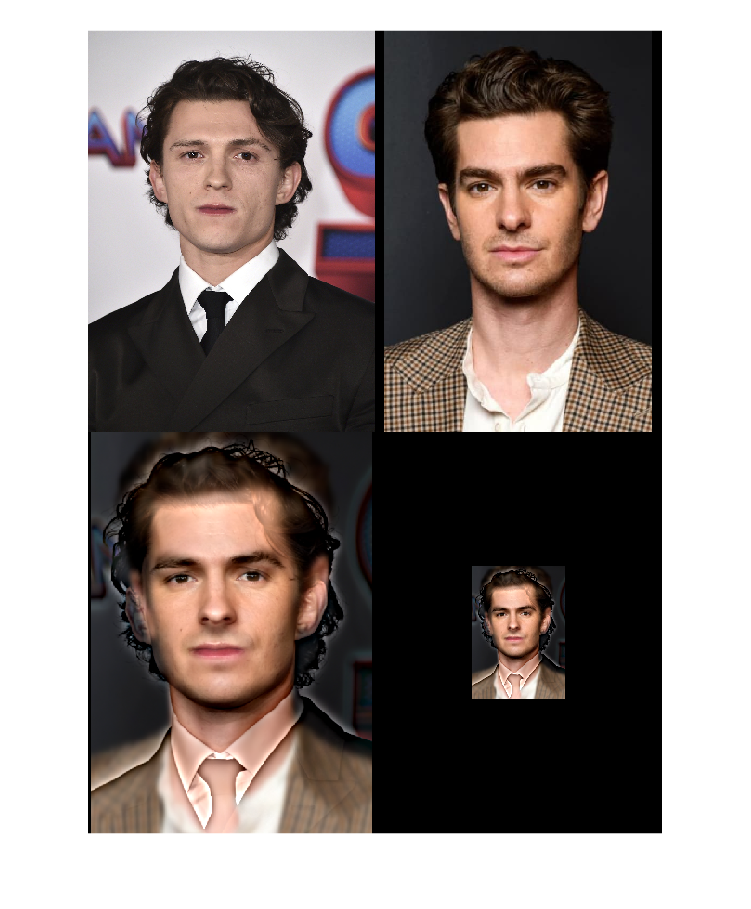

fig=figure; hold off, imagesc(set2_hybrid), axis image;
 figure(fig)
% [x, y] = ginput(2); 
% x = round(x)
% y = round(y)
 close(fig);
% Once you have these coordinates, comment the lines above, and 
% hard code the values below.
x = [59
   507];
y = [229
   869];

set2_hybrid = set2_hybrid(min(y):max(y), min(x):max(x), :);

% Let us try to "simulate" what the hybrid image will look like
% when viewed from afar.  Let us pad a black border around it
% so it effectively shrinks in size when displayed in a montage.
[h, w, ~] = size(set2_hybrid);
viewed_from_afar = padarray(set2_hybrid, max(h, w));
figure; montage({set2_near, set2_far, set2_hybrid, viewed_from_afar}, 'Size', [2,2]);





% REPEAT ABOVE FOR IMAGE SET 3
set3_far = im2double(imread('https://imgur.com/M2MGhw8.jpg')); 	
set3_far = resize(set3_far);% "far" picture
set3_near = im2double(imread('https://imgur.com/K9d3Q9r.jpg')); 
set3_near = resize(set3_near);% "near" picture
% (Optional) convert images to grayscale
% set2_far = rgb2gray(set2_far);                
% set2_near = rgb2gray(set2_near);

% Interactively get two pairs of points from each image to establish
% alignment.
%  [x1, y1, x2, y2] = get_points_interactively(set3_near, set3_far)
% Once you have these coordinates, comment out call to the interactive
% function above and hard code the coordinates instead.
x1 = [231.0327
  311.6402];
y1 =[253.4206
  254.5888];
x2 =[219.0140
  292.6121];
y2 =[270.9439
  272.1121];

[set3_near_aligned, set3_far_aligned] = align_images(set3_near, set3_far, x1, y1, x2, y2);

% Choose the cutoff frequencies for the low-pass and high-pass filters
% CHOOSE CAREFULLY!  Values will depend on the images used!
cutoff_low  = 12.5;   % provide a value for the low-pass filter cutoff frequency (sigma of gaussian)
cutoff_high = 1.0;   % provide a value for the high-pass filter cutoff frequency (sigma of gaussian)


% Compute the hybrid image (you supply this code)
set3_hybrid = hybridImage(set3_far_aligned, set3_near_aligned, cutoff_low, cutoff_high);

% Crop resulting image:  Crop the result to get rid of any unsightly borders areas.
disp('input crop points (two opposite corners)');

input crop points (two opposite corners)


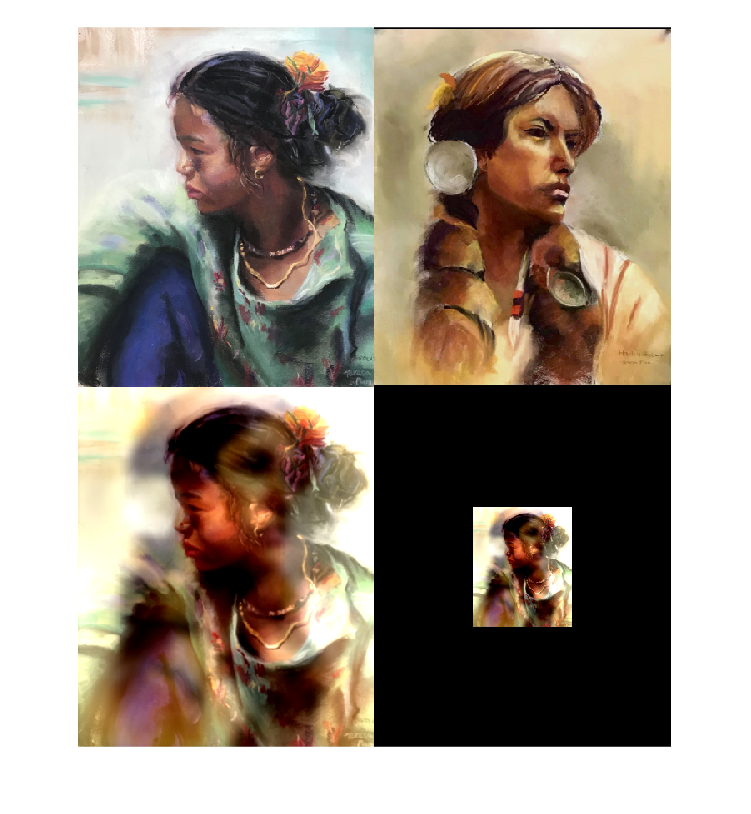

fig=figure; hold off, imagesc(set3_hybrid), axis image;
figure(fig)
%  [x, y] = ginput(2); 
%  x = round(x)
%  y = round(y)
close(fig);
% Once you have these coordinates, comment the lines above, and 
% hard code the values below.
x =[8
   373];
y =[9
   453];


set3_hybrid = set3_hybrid(min(y):max(y), min(x):max(x), :);

% Let us try to "simulate" what the hybrid image will look like
% when viewed from afar.  Let us pad a black border around it
% so it effectively shrinks in size when displayed in a montage.
[h, w, ~] = size(set3_hybrid);
viewed_from_afar = padarray(set3_hybrid, max(h, w));
figure; montage({set3_near, set3_far, set3_hybrid, viewed_from_afar}, 'Size', [2,2]);



% REPEAT ABOVE FOR IMAGE SET 4
set4_far = im2double(imread('https://imgur.com/wRF8iTu.jpg')); 	
set4_far = resize(set4_far);% "far" picture
set4_near = im2double(imread('https://imgur.com/SQNqJbO.jpg')); 
set4_near = resize(set4_near);% "near" picture
% (Optional) convert images to grayscale
set4_far = rgb2gray(set4_far);                
set4_near = rgb2gray(set4_near);

% Interactively get two pairs of points from each image to establish
% alignment.
%   [x1, y1, x2, y2] = get_points_interactively(set4_near, set4_far)
% Once you have these coordinates, comment out call to the interactive
% function above and hard code the coordinates instead.
x2 =[92.4346
  145.0047];
y2 =[288.4673
  294.3084];
x1 =[208.4439
  282.0421];
y1 =[234.7290
  234.7290];


[set4_near_aligned, set4_far_aligned] = align_images(set4_near, set4_far, x1, y1, x2, y2);

% Choose the cutoff frequencies for the low-pass and high-pass filters
% CHOOSE CAREFULLY!  Values will depend on the images used!
cutoff_low  = 25.0;   % provide a value for the low-pass filter cutoff frequency (sigma of gaussian)
cutoff_high = 5.0;   % provide a value for the high-pass filter cutoff frequency (sigma of gaussian)


% Compute the hybrid image (you supply this code)
set4_hybrid = hybridImage(set4_far_aligned, set4_near_aligned, cutoff_low, cutoff_high);

% Crop resulting image:  Crop the result to get rid of any unsightly borders areas.
disp('input crop points (two opposite corners)');

input crop points (two opposite corners)


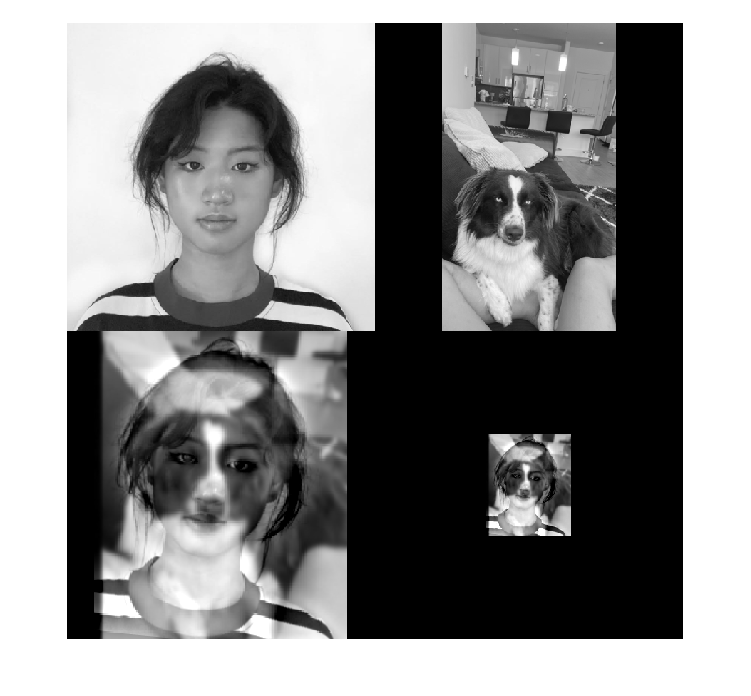

fig=figure; hold off, imagesc(set4_hybrid), axis image;
figure(fig)
%  [x, y] = ginput(2); 
%  x = round(x)
%  y = round(y)
close(fig);
% Once you have these coordinates, comment the lines above, and 
% hard code the values below.
x = [38
   306];

y =[71
   398];


set4_hybrid = set4_hybrid(min(y):max(y), min(x):max(x), :);

% Let us try to "simulate" what the hybrid image will look like
% when viewed from afar.  Let us pad a black border around it
% so it effectively shrinks in size when displayed in a montage.
[h, w, ~] = size(set4_hybrid);
viewed_from_afar = padarray(set4_hybrid, max(h, w));
figure; montage({set4_near, set4_far, set4_hybrid, viewed_from_afar}, 'Size', [2,2]);


% REPEAT ABOVE FOR IMAGE SET 5
set4_far = im2double(imread('https://upload.wikimedia.org/wikipedia/commons/6/60/Xi_Jinping_portrait_2019_%28cropped%29.jpg')); 	
set4_far = resize(set4_far);% "far" picture
set4_near = im2double(imread('https://upload.wikimedia.org/wikipedia/commons/6/6e/Kim_Jong-un_April_2019_%28cropped%29.jpg')); 
set4_near = resize(set4_near);% "near" picture
% (Optional) convert images to grayscale
set4_far = rgb2gray(set4_far);                
set4_near = rgb2gray(set4_near);

% Interactively get two pairs of points from each image to establish
% alignment.
%   [x1, y1, x2, y2] = get_points_interactively(set4_near, set4_far)
% Once you have these coordinates, comment out call to the interactive
% function above and hard code the coordinates instead.
x1 =[151.2944
  212.0421];
y1 =[138.9346
  137.7664];
x2 =[169.3318
  233.5841];
y2 =[157.6262
  163.4673];



[set4_near_aligned, set4_far_aligned] = align_images(set4_near, set4_far, x1, y1, x2, y2);

% Choose the cutoff frequencies for the low-pass and high-pass filters
% CHOOSE CAREFULLY!  Values will depend on the images used!
cutoff_low  = 30.0;   % provide a value for the low-pass filter cutoff frequency (sigma of gaussian)
cutoff_high = 15.0;   % provide a value for the high-pass filter cutoff frequency (sigma of gaussian)


% Compute the hybrid image (you supply this code)
set4_hybrid = hybridImage(set4_far_aligned, set4_near_aligned, cutoff_low, cutoff_high);

% Crop resulting image:  Crop the result to get rid of any unsightly borders areas.
disp('input crop points (two opposite corners)');

input crop points (two opposite corners)


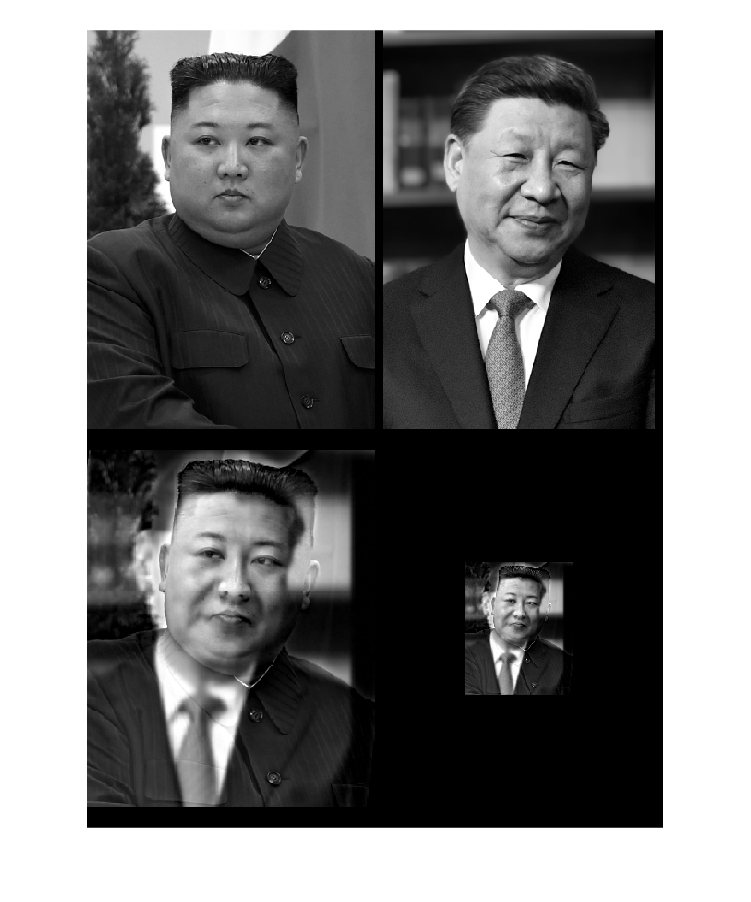

fig=figure; hold off, imagesc(set4_hybrid), axis image;
figure(fig)
%  [x, y] = ginput(2); 
%  x = round(x)
%  y = round(y)
close(fig);
% Once you have these coordinates, comment the lines above, and 
% hard code the values below.
x = [19
   346];
y = [199
   604];


set4_hybrid = set4_hybrid(min(y):max(y), min(x):max(x), :);

% Let us try to "simulate" what the hybrid image will look like
% when viewed from afar.  Let us pad a black border around it
% so it effectively shrinks in size when displayed in a montage.
[h, w, ~] = size(set4_hybrid);
viewed_from_afar = padarray(set4_hybrid, max(h, w));
figure; montage({set4_near, set4_far, set4_hybrid, viewed_from_afar}, 'Size', [2,2]);




% REPEAT ABOVE FOR IMAGE SET 6
set4_far = im2double(imread('https://horse-canada.com/wp-content/uploads/2020/07/DonkeyFeatureLangrish.jpg')); 	
set4_far = resize(set4_far);% "far" picture
set4_near = im2double(imread('https://upload.wikimedia.org/wikipedia/commons/6/60/Equus_quagga.jpg')); 
set4_near = resize(set4_near);% "near" picture
% (Optional) convert images to grayscale
% set4_far = rgb2gray(set4_far);                
% set4_near = rgb2gray(set4_near);

% Interactively get two pairs of points from each image to establish
% alignment.
%   [x1, y1, x2, y2] = get_points_interactively(set4_near, set4_far)
% Once you have these coordinates, comment out call to the interactive
% function above and hard code the coordinates instead.
x1 =[189.7265
  376.6510];
y1 = [158.2523
  164.6980];
x2 =[191.5681
  360.9972];
y2 =[85.9199
   88.6823];



[set4_near_aligned, set4_far_aligned] = align_images(set4_near, set4_far, x1, y1, x2, y2);

% Choose the cutoff frequencies for the low-pass and high-pass filters
% CHOOSE CAREFULLY!  Values will depend on the images used!
cutoff_low  = 25.0;   % provide a value for the low-pass filter cutoff frequency (sigma of gaussian)
cutoff_high = 8.0;   % provide a value for the high-pass filter cutoff frequency (sigma of gaussian)


% Compute the hybrid image (you supply this code)
set4_hybrid = hybridImage(set4_far_aligned, set4_near_aligned, cutoff_low, cutoff_high);

% Crop resulting image:  Crop the result to get rid of any unsightly borders areas.
disp('input crop points (two opposite corners)');

input crop points (two opposite corners)


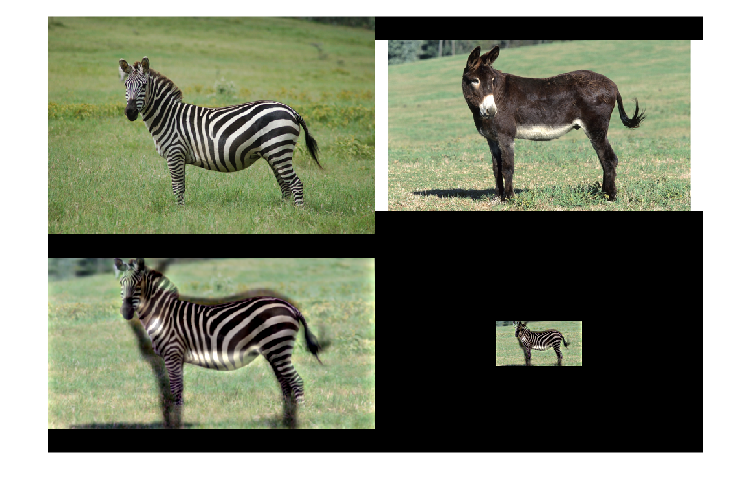

fig=figure; hold off, imagesc(set4_hybrid), axis image;
figure(fig)
%  [x, y] = ginput(2); 
%  x = round(x)
%  y = round(y)
close(fig);
% Once you have these coordinates, comment the lines above, and 
% hard code the values below.
x =[12
   455];
y = [78
   309];



set4_hybrid = set4_hybrid(min(y):max(y), min(x):max(x), :);

% Let us try to "simulate" what the hybrid image will look like
% when viewed from afar.  Let us pad a black border around it
% so it effectively shrinks in size when displayed in a montage.
[h, w, ~] = size(set4_hybrid);
viewed_from_afar = padarray(set4_hybrid, max(h, w));
figure; montage({set4_near, set4_far, set4_hybrid, viewed_from_afar}, 'Size', [2,2]);




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Your function appears below 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


function im12 = hybridImage(im1_far, im2_near, cutoff_low, cutoff_high)
    imf = fftshift(fft2(im1_far));
    imn = fftshift(fft2(im2_near));
    [hf wf ~] = size(im1_far);
    [hn wn ~] = size(im2_near);

    hfar = fspecial('gaussian', [hf wf] ,cutoff_low);
    hfar = hfar./max(max(hfar));
    gausf = imf.*hfar;

    hnear = fspecial('gaussian', [hn wn],cutoff_high);
    hnear = hnear./max(max(hnear));
    gausn = imn.*(1-hnear);

    gaus = gausf + gausn;

    im12 = real(ifft2(ifftshift(gaus)));

    
end



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Helper functions. (You DO NOT need to change)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [x1, y1, x2, y2] = get_points_interactively(im1, im2)
    % displays image and gets two points from the user
    fig=figure; hold off, imagesc(im1), axis image;
    disp('Select two points from each image define rotation, scale, translation')
    figure(fig)
    [x1, y1] = ginput(2);
    figure(fig); hold off, imagesc(im2), axis image;
    figure(fig)
    [x2, y2] = ginput(2);
    close(fig);
end
function result = resize(im)
    [h w ~] = size(im);
    maxsize = 500;
    %resize the picture so it is not too big
    if(h >= w)
        result = imresize(im, [maxsize, NaN]);
    else
        result = imresize(im, [NaN, maxsize]);
    end
end
function [im1, im2] = align_images(im1, im2, x1, y1, x2, y2)
    % Aligns im1 and im2 (translation, scale, rotation) after getting two pairs
    % of points from the user.  In the output of im1 and im2, the two pairs of
    % points will have approximately the same coordinates.
    
    % get image sizes
    [h1, w1, ~] = size(im1);
    [h2, w2, ~] = size(im2);
    
    cx1 = mean(x1); cy1 = mean(y1);
    cx2 = mean(x2); cy2 = mean(y2);
    
    % translate first so that center of ref points is center of image
    tx = round((w1/2-cx1)*2);
    if tx > 0,  im1 = padarray(im1, [0 tx], 'pre');
    else        im1 = padarray(im1, [0 -tx], 'post');
    end
    ty = round((h1/2-cy1)*2);
    if ty > 0,  im1 = padarray(im1, [ty 0], 'pre');
    else        im1 = padarray(im1, [-ty 0], 'post');
    end  
    tx = round((w2/2-cx2)*2) ;
    if tx > 0,  im2 = padarray(im2, [0 tx], 'pre');
    else        im2 = padarray(im2, [0 -tx], 'post');
    end
    ty = round((h2/2-cy2)*2);
    if ty > 0,  im2 = padarray(im2, [ty 0], 'pre');
    else        im2 = padarray(im2, [-ty 0], 'post');
    end
    
    % downscale larger image so that lengths between ref points are the same
    len1 = sqrt((y1(2)-y1(1)).^2+(x1(2)-x1(1)).^2);
    len2 = sqrt((y2(2)-y2(1)).^2+(x2(2)-x2(1)).^2);
    dscale = len2 ./ len1;
    if dscale < 1
        im1 = imresize(im1, dscale, 'bilinear'); 
    else
        im2 = imresize(im2, 1./dscale, 'bilinear');
    end
    
    % rotate im1 so that angle between points is the same
    theta1 = atan2(-(y1(2)-y1(1)), x1(2)-x1(1)); % in matlab, y==1 is at the top of the N x M image, and y==N is at the bottom
    theta2 = atan2(-(y2(2)-y2(1)), x2(2)-x2(1));
    dtheta = theta2-theta1;
    im1 = imrotate(im1, dtheta*180/pi, 'bilinear'); % imrotate uses degree units
    
    % Crop images (on both sides of border) to be same height and width
    [h1, w1, ~] = size(im1);
    [h2, w2, ~] = size(im2);
    
    minw = min(w1, w2);
    brd = (max(w1, w2)-minw)/2;
    if minw == w1 % crop w2
        im2 = im2(:, (ceil(brd)+1):end-floor(brd), :);
        tx = tx-ceil(brd);
    else
        im1 = im1(:, (ceil(brd)+1):end-floor(brd), :);
        tx = tx+ceil(brd);    
    end
    
    minh = min(h1, h2);
    brd = (max(h1, h2)-minh)/2;
    if minh == h1 % crop w2
        im2 = im2((ceil(brd)+1):end-floor(brd), :, :);
        ty = ty-ceil(brd);
    else
        im1 = im1((ceil(brd)+1):end-floor(brd), :, :);
        ty = ty+ceil(brd);    
    end    
end

